clear;
clc;
bode_plot_options = bodeoptions();
bode_plot_options.Grid = 'on';

# Plant

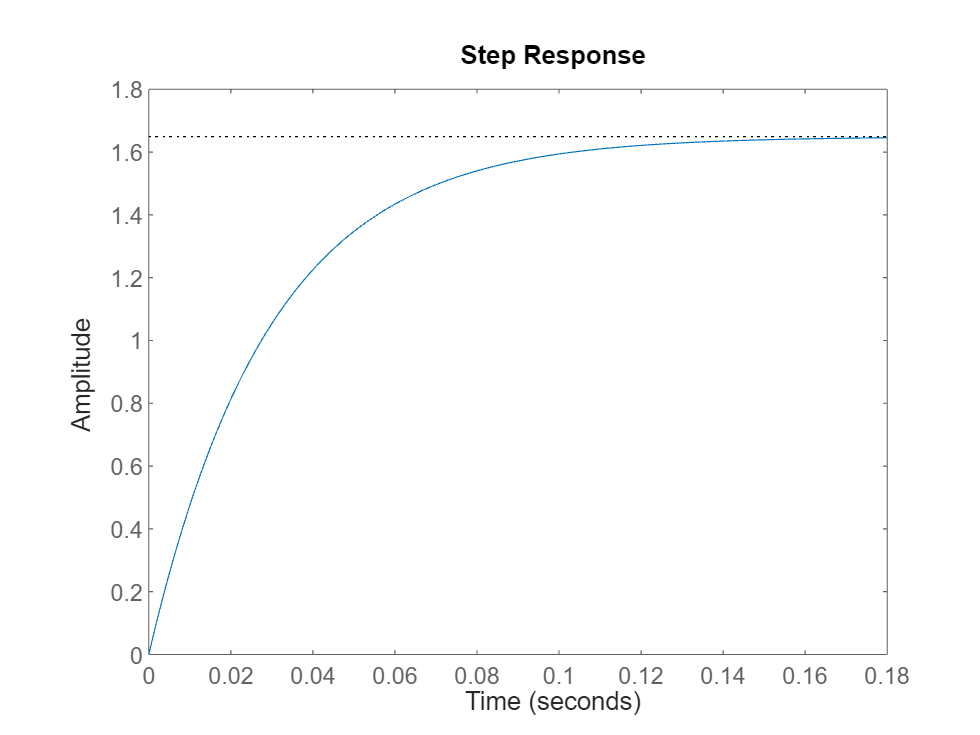

s = tf('s');
plant_tf = 55.99/(s+33.95);
step_response_parameters = stepinfo(plant_tf);
plant_tr = step_response_parameters.RiseTime;
step(plant_tf);

# Control Design

#### Requirements

Error Position [Ep] = 0;

disp(0.7*plant_tr);

    0.0453



Rise Time [tr] <= 0.0453s;

## PI Sintonization

%pidTuner(plant_tf);

#### Results

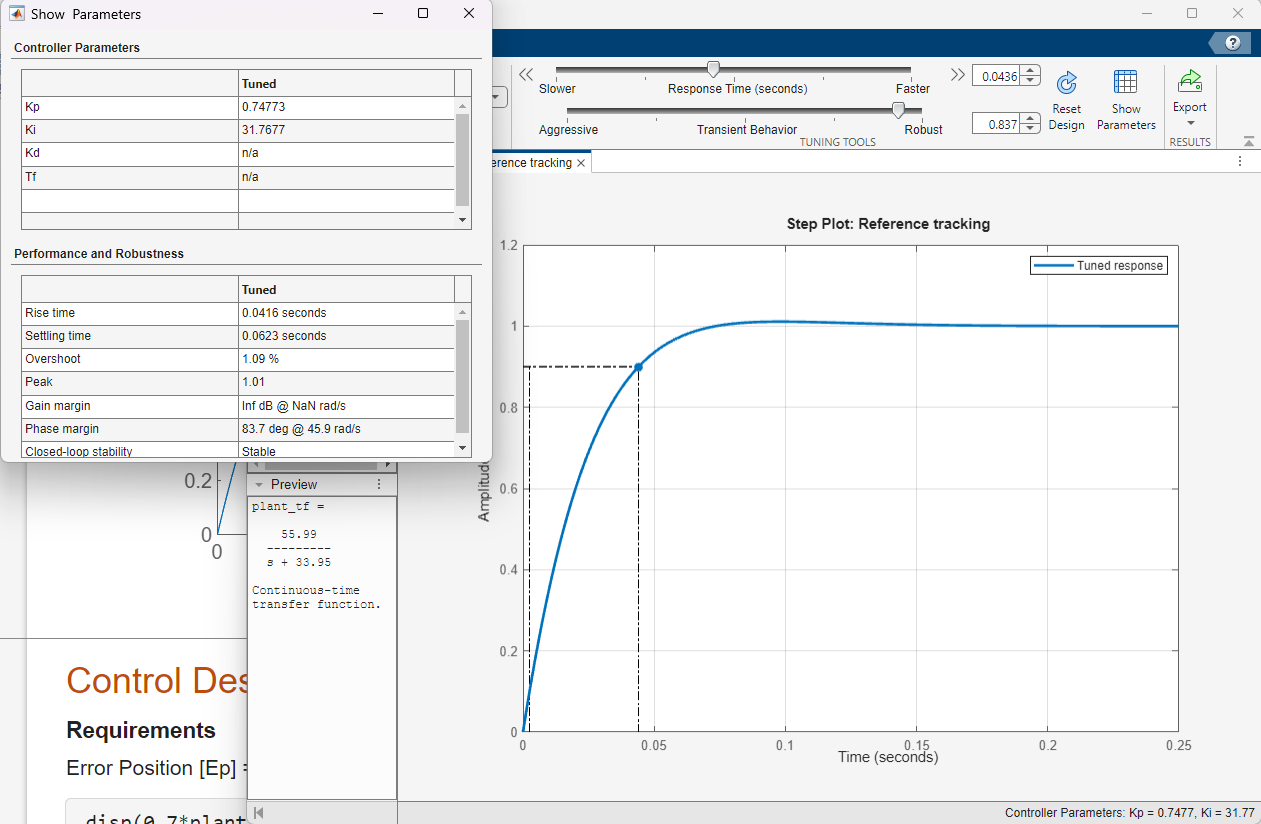

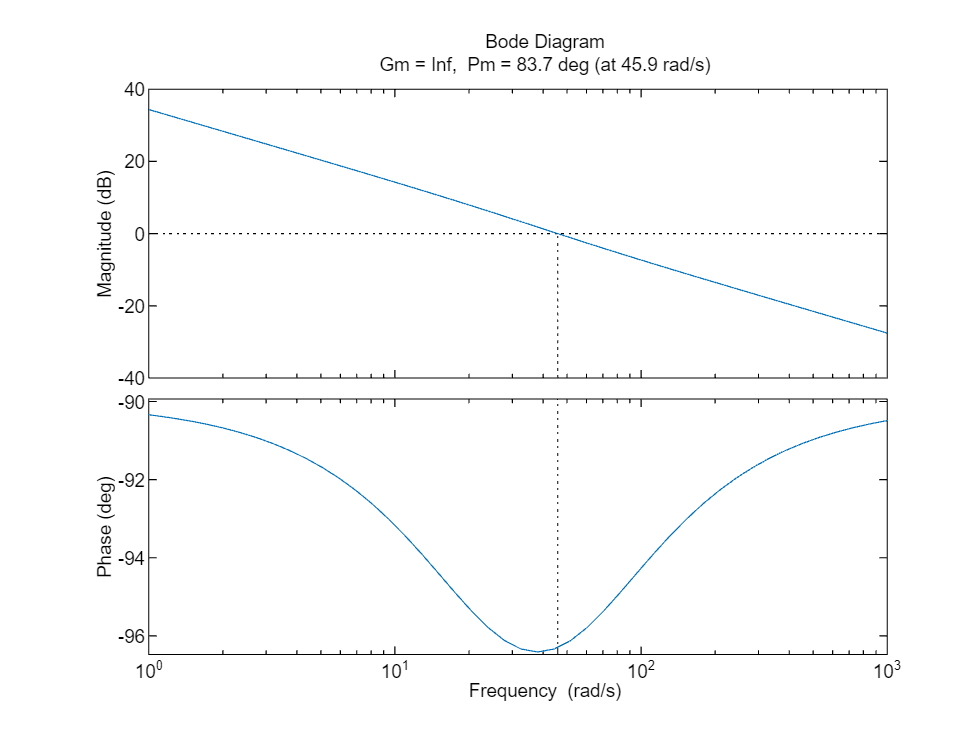

Kp = 0.74773;
Ki = 31.7677;
pi_ctrl_tf = Kp + Ki/s;
margin(pi_ctrl_tf*plant_tf,bodeoptions);

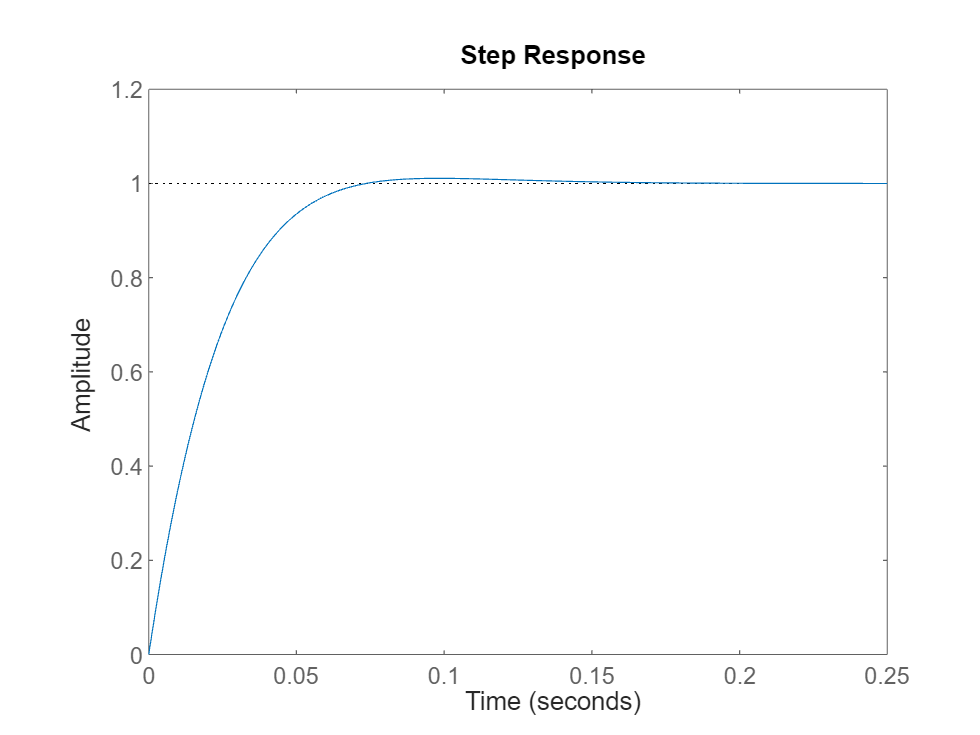

step(feedback(pi_ctrl_tf*plant_tf,1));

## Discretization

Ts = 0.005;
syms s z;
pi_ctrl_tf_sym = poly2sym(cell2mat(pi_ctrl_tf.Numerator),s)/poly2sym(cell2mat(pi_ctrl_tf.Denominator),s);

### Impulse Invariance

pi_ctrl_tf_z_in = c2d(pi_ctrl_tf,Ts,'impulse')

pi_ctrl_tf_z_in =
 
  0.1588 z - 4.988e-17
  --------------------
         z - 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


### Step Invariance (ZOH)

pi_ctrl_tf_z_zoh = c2d(pi_ctrl_tf,Ts,'zoh')

pi_ctrl_tf_z_zoh =
 
  0.7477 z - 0.5889
  -----------------
        z - 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


### Forward Approximation 

[num,den] = numden(subs(pi_ctrl_tf_sym,s,(z-1)/(Ts)));
[num,den] = tfdata(zpk(tf(sym2poly(num),sym2poly(den),Ts)));
pi_ctrl_tf_z_fa = tf(cell2mat(num),cell2mat(den),Ts)

pi_ctrl_tf_z_fa =
 
  0.7477 z - 0.5889
  -----------------
        z - 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


### Backward Approximation 

[num,den] = numden(subs(pi_ctrl_tf_sym,s,(z-1)/(Ts*z)));
[num,den] = tfdata(zpk(tf(sym2poly(num),sym2poly(den),Ts)));
pi_ctrl_tf_z_ba = tf(cell2mat(num),cell2mat(den),Ts)

pi_ctrl_tf_z_ba =
 
  0.9066 z - 0.7477
  -----------------
        z - 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


### Tustin 

pi_ctrl_tf_z_tus = c2d(pi_ctrl_tf,Ts,'tustin')

pi_ctrl_tf_z_tus =
 
  0.8271 z - 0.6683
  -----------------
        z - 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


### Poles and Zeros Maping

pi_ctrl_tf_z_pzm = c2d(pi_ctrl_tf,Ts,'matched')

pi_ctrl_tf_z_pzm =
 
  0.83 z - 0.6711
  ---------------
       z - 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


# Bandwidth Verification

fs=200hz (5ms) must be at least 20 times the bandwidth in closed loop

plant_tf_z = c2d(plant_tf,Ts,'zoh');
disp("Impulse Invariance Controller Bandwidth: " + num2str(bandwidth(feedback(pi_ctrl_tf_z_in*plant_tf_z,1))/(2*pi)) + " Hz");

Impulse Invariance Controller Bandwidth: 9.2564 Hz


disp("Step Invariance Controller Bandwidth: " + num2str(bandwidth(feedback(pi_ctrl_tf_z_zoh*plant_tf_z,1))/(2*pi)) + " Hz");

Step Invariance Controller Bandwidth: 8.9244 Hz


disp("Forward Approximation Controller Bandwidth: " + num2str(bandwidth(feedback(pi_ctrl_tf_z_fa*plant_tf_z,1))/(2*pi)) + " Hz");

Forward Approximation Controller Bandwidth: 8.9244 Hz


disp("Backward Approximation Controller Bandwidth: " + num2str(bandwidth(feedback(pi_ctrl_tf_z_ba*plant_tf_z,1))/(2*pi)) + " Hz");

Backward Approximation Controller Bandwidth: 9.305 Hz


disp("Tustin Controller Bandwidth: " + num2str(bandwidth(feedback(pi_ctrl_tf_z_tus*plant_tf_z,1))/(2*pi)) + " Hz");

Tustin Controller Bandwidth: 9.0849 Hz


disp("Pole Zero Mapping Controller Bandwidth: " + num2str(bandwidth(feedback(pi_ctrl_tf_z_pzm*plant_tf_z,1))/(2*pi)) + " Hz");

Pole Zero Mapping Controller Bandwidth: 9.0916 Hz


# Final Controllers

pi_ctrl_tf_z_in_neg = tf(cell2mat(pi_ctrl_tf_z_in.Numerator),cell2mat(pi_ctrl_tf_z_in.Denominator),Ts,"variable",'z^-1')

pi_ctrl_tf_z_in_neg =
 
  0.1588 - 4.988e-17 z^-1
  -----------------------
         1 - z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


pi_ctrl_tf_z_zoh_neg = tf(cell2mat(pi_ctrl_tf_z_zoh.Numerator),cell2mat(pi_ctrl_tf_z_zoh.Denominator),Ts,"variable",'z^-1')

pi_ctrl_tf_z_zoh_neg =
 
  0.7477 - 0.5889 z^-1
  --------------------
        1 - z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


pi_ctrl_tf_z_fa_neg = tf(cell2mat(pi_ctrl_tf_z_fa.Numerator),cell2mat(pi_ctrl_tf_z_fa.Denominator),Ts,"variable",'z^-1')

pi_ctrl_tf_z_fa_neg =
 
  0.7477 - 0.5889 z^-1
  --------------------
        1 - z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


pi_ctrl_tf_z_ba_neg = tf(cell2mat(pi_ctrl_tf_z_ba.Numerator),cell2mat(pi_ctrl_tf_z_ba.Denominator),Ts,"variable",'z^-1')

pi_ctrl_tf_z_ba_neg =
 
  0.9066 - 0.7477 z^-1
  --------------------
        1 - z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


pi_ctrl_tf_z_tus_neg = tf(cell2mat(pi_ctrl_tf_z_tus.Numerator),cell2mat(pi_ctrl_tf_z_tus.Denominator),Ts,"variable",'z^-1')

pi_ctrl_tf_z_tus_neg =
 
  0.8271 - 0.6683 z^-1
  --------------------
        1 - z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


pi_ctrl_tf_z_pzm_neg = tf(cell2mat(pi_ctrl_tf_z_pzm.Numerator),cell2mat(pi_ctrl_tf_z_pzm.Denominator),Ts,"variable",'z^-1')

pi_ctrl_tf_z_pzm_neg =
 
  0.83 - 0.6711 z^-1
  ------------------
       1 - z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


# Discretizations Comparison 

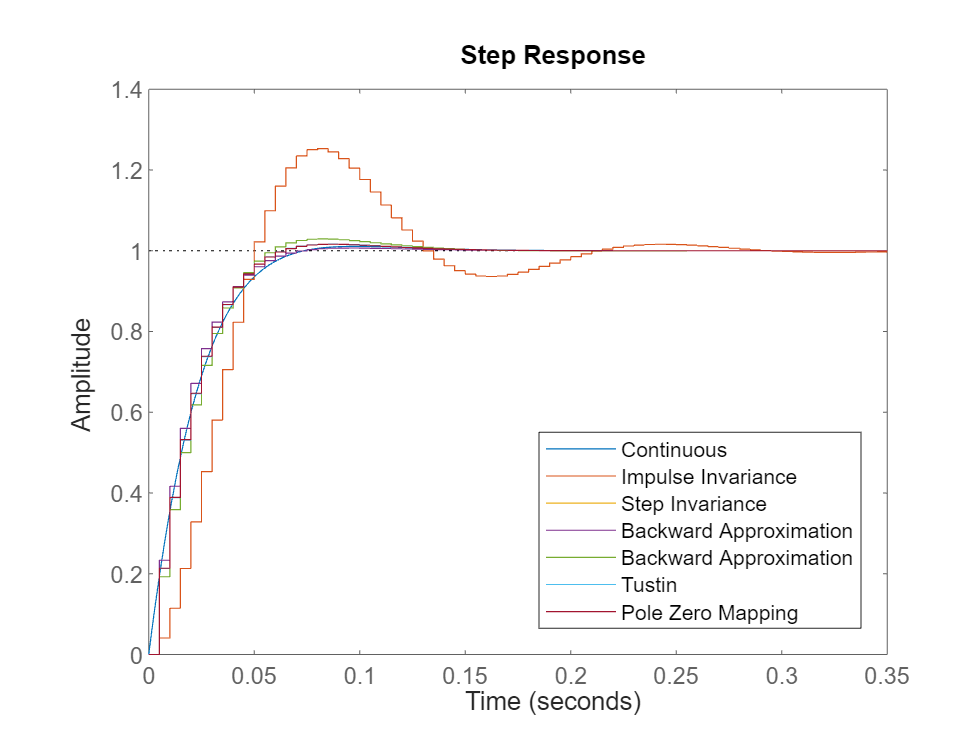

figure;
hold on;
step(feedback(pi_ctrl_tf*plant_tf,1));
step(feedback(pi_ctrl_tf_z_in_neg*c2d(plant_tf,Ts,'zoh'),1));
step(feedback(pi_ctrl_tf_z_zoh_neg*c2d(plant_tf,Ts,'zoh'),1));
step(feedback(pi_ctrl_tf_z_ba_neg*c2d(plant_tf,Ts,'zoh'),1));
step(feedback(pi_ctrl_tf_z_fa_neg*c2d(plant_tf,Ts,'zoh'),1));
step(feedback(pi_ctrl_tf_z_tus_neg*c2d(plant_tf,Ts,'zoh'),1));
step(feedback(pi_ctrl_tf_z_pzm_neg*c2d(plant_tf,Ts,'zoh'),1));
legend('Continuous','Impulse Invariance','Step Invariance','Backward Approximation','Backward Approximation','Tustin','Pole Zero Mapping');
legend("Position", [0.5506,0.14569,0.32857,0.26667]);

# Comparison with Real Data

time = (0:0.005:8);

#### Inpulse Invariance

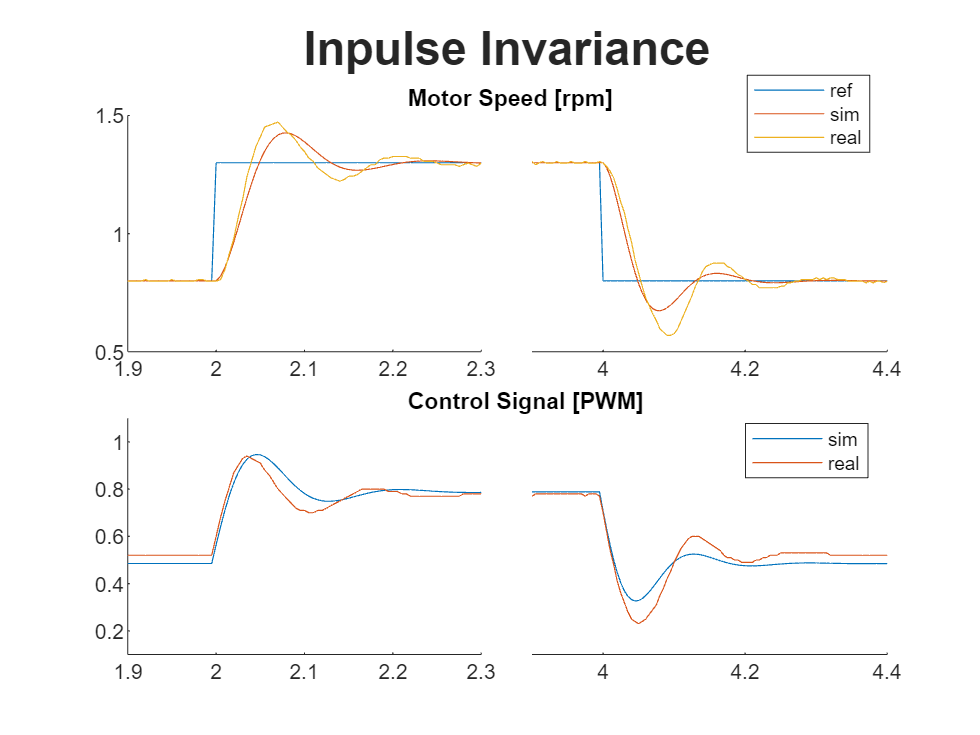

[real_omega_iin, real_u_iin] = data_loader.square_signal_loader('result/pi_iin.csv',200,4,0.8,1.3);
figure;
tiles=tiledlayout(2,2);
tiles.TileSpacing = 'tight';
t = title(tiles,'Inpulse Invariance');
t.FontName='Times New Roman';
t.FontSize=20;
t.FontWeight='bold';

plt1=nexttile;
hold on;
plot(plt1,time, out.ref_iin);
plot(plt1,time, out.omega_iin);
plot(plt1,time, real_omega_iin);
axis(plt1,[1.9 2.3 0.5 1.5]);
title(plt1,'                Motor Speed [rpm]','HorizontalAlignment','left');

plt2=nexttile;
hold on;
plot(plt2,time, out.ref_iin);
plot(plt2,time, out.omega_iin);
plot(plt2,time, real_omega_iin);
axis(plt2,[3.9 4.4 0.5 1.5]);
legend(plt2,'ref','sim','real');
legend("Position", [0.76299,0.79212,0.125,0.10476]);
plt2.YAxis.Visible = 'off';

plt3=nexttile;
hold on;
plot(plt3,time, out.u_iin);
plot(plt3,time, real_u_iin);
axis(plt3,[1.9 2.3 0.1 1.1]);
title(plt3,'                Control Signal [PWM]','HorizontalAlignment','left');

plt4=nexttile;
hold on;
plot(plt4,time, out.u_iin);
plot(plt4,time, real_u_iin);
axis(plt4,[3.9 4.4 0.1 1.1]);
legend(plt4,'sim','real');
legend("Position", [0.76095,0.35085,0.125,0.072619]);
plt4.YAxis.Visible = 'off';

#### Step Invariance

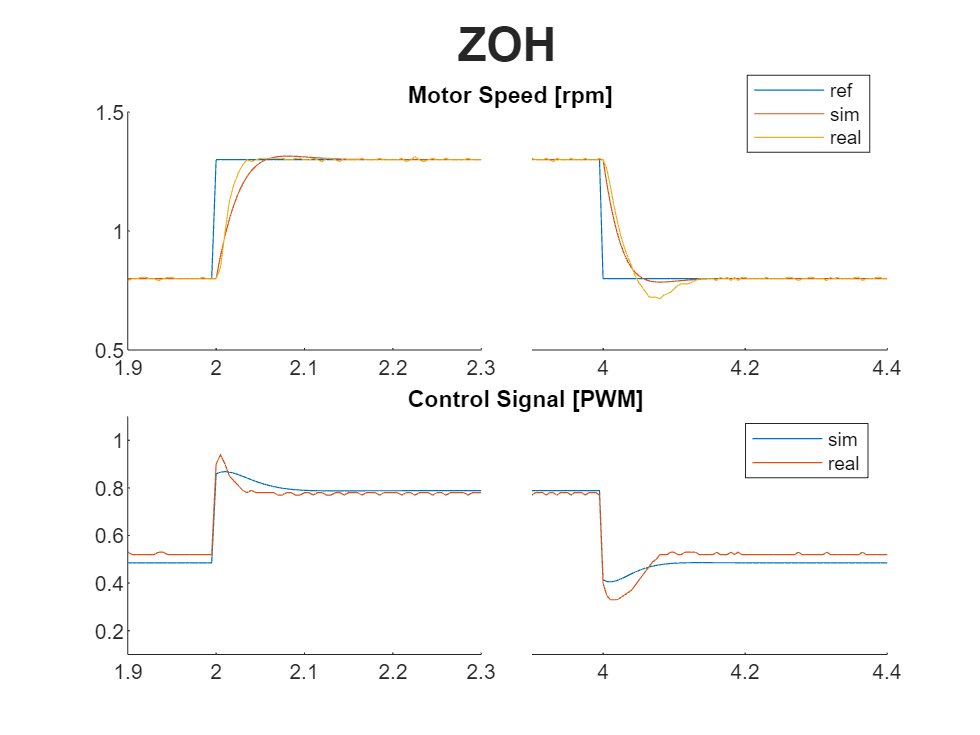

[real_omega_zoh, real_u_zoh] = data_loader.square_signal_loader('result/pi_zoh.csv',200,4,0.8,1.3);
figure;
tiles=tiledlayout(2,2);
tiles.TileSpacing = 'tight';
t = title(tiles,'ZOH');
t.FontName='Times New Roman';
t.FontSize=20;
t.FontWeight='bold';

plt1=nexttile;
hold on;
plot(plt1,time, out.ref_zoh);
plot(plt1,time, out.omega_zoh);
plot(plt1,time, real_omega_zoh);
axis(plt1,[1.9 2.3 0.5 1.5]);
title(plt1,'                Motor Speed [rpm]','HorizontalAlignment','left');

plt2=nexttile;
hold on;
plot(plt2,time, out.ref_zoh);
plot(plt2,time, out.omega_zoh);
plot(plt2,time, real_omega_zoh);
axis(plt2,[3.9 4.4 0.5 1.5]);
legend(plt2,'ref','sim','real');
legend("Position", [0.76299,0.79212,0.125,0.10476]);
plt2.YAxis.Visible = 'off';

plt3=nexttile;
hold on;
plot(plt3,time, out.u_zoh);
plot(plt3,time, real_u_zoh);
axis(plt3,[1.9 2.3 0.1 1.1]);
title(plt3,'                Control Signal [PWM]','HorizontalAlignment','left');

plt4=nexttile;
hold on;
plot(plt4,time, out.u_zoh);
plot(plt4,time, real_u_zoh);
axis(plt4,[3.9 4.4 0.1 1.1]);
legend(plt4,'sim','real');
legend("Position", [0.76095,0.35085,0.125,0.072619]);
plt4.YAxis.Visible = 'off';

#### Tustin

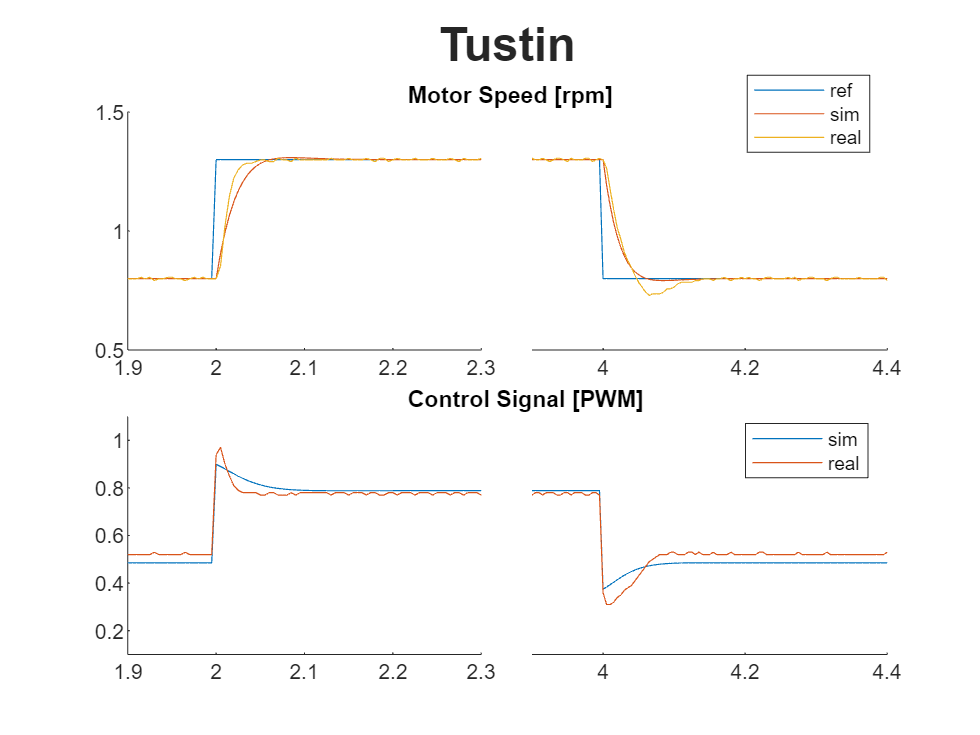

[real_omega_tus, real_u_tus] = data_loader.square_signal_loader('result/pi_tus.csv',200,4,0.8,1.3);
figure;
tiles=tiledlayout(2,2);
tiles.TileSpacing = 'tight';
t=title(tiles,'Tustin');
t.FontName='Times New Roman';
t.FontSize=20;
t.FontWeight='bold';

plt1=nexttile;
hold on;
plot(plt1,time, out.ref_tus);
plot(plt1,time, out.omega_tus);
plot(plt1,time, real_omega_tus);
axis(plt1,[1.9 2.3 0.5 1.5]);
title(plt1,'                Motor Speed [rpm]','HorizontalAlignment','left');

plt2=nexttile;
hold on;
plot(plt2,time, out.ref_tus);
plot(plt2,time, out.omega_tus);
plot(plt2,time, real_omega_tus);
axis(plt2,[3.9 4.4 0.5 1.5]);
legend(plt2,'ref','sim','real');
legend("Position", [0.76299,0.79212,0.125,0.10476]);
plt2.YAxis.Visible = 'off';

plt3=nexttile;
hold on;
plot(plt3,time, out.u_tus);
plot(plt3,time, real_u_tus);
axis(plt3,[1.9 2.3 0.1 1.1]);
title(plt3,'                Control Signal [PWM]','HorizontalAlignment','left');

plt4=nexttile;
hold on;
plot(plt4,time, out.u_tus);
plot(plt4,time, real_u_tus);
axis(plt4,[3.9 4.4 0.1 1.1]);
legend(plt4,'sim','real');
legend("Position", [0.76095,0.35085,0.125,0.072619]);
plt4.YAxis.Visible = 'off';